b = 60;                 % baseline [mm]
f = 6;                  % focal length [mm]
ps = .006;              % pixel size [mm]
xNumPix = 752;          % total number of pixels in x direction of the sensor [px]
cxLeft = xNumPix/2;     % left camera x center [px]
cxRight = xNumPix/2;    % right camera x center [px]
xLeft = 476;
xRight = 276;

d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps)  % disparity [mm]

d = 1.2000

Z = (b * f)/d                                  % depth [mm]

Z = 300

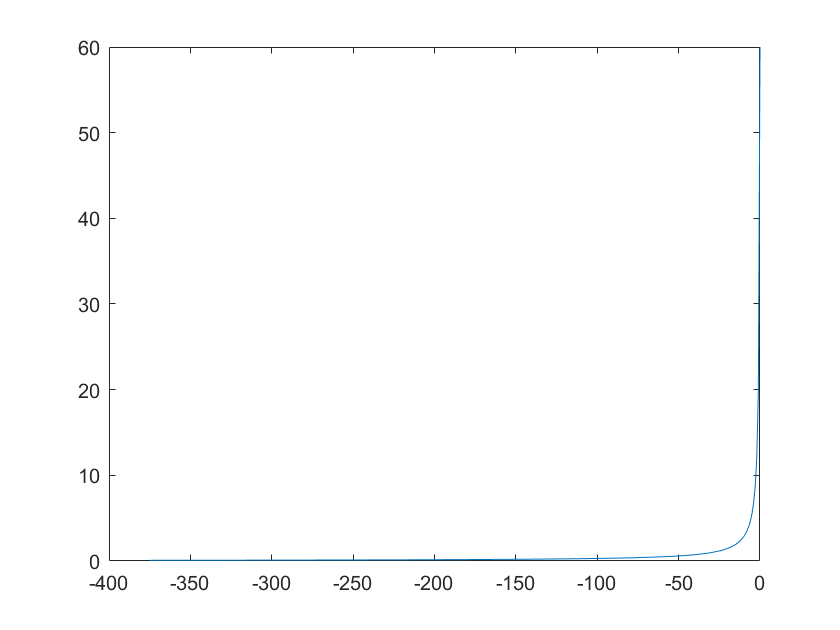

x = 1:752/2;
xLeft = x;
xRight = 753-x;
d = (abs((xLeft-cxLeft)-(xRight-cxRight)).*ps);  % disparity [mm]
Z = (b * f)./d;                                  % depth [mm]
Z = Z./1000;
plot(xLeft-cxLeft,Z);